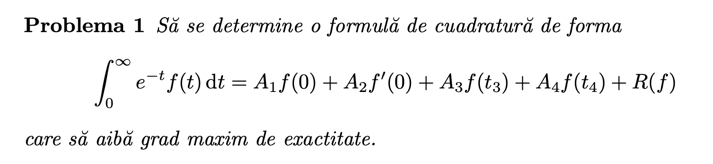

## Solutie

Vom rezolva folosind metoda coeficientilor nedeterminati. Avand 6 necunoscute, avem nevoie de 6 momente:

function rest=RR(f,A1,A2,A3,A4,t3,t4)
    syms t
    val_int=int(exp(-t)*f(t),t,0,inf);
    val_quad=A1*subs(f(t), t, 0) + A2*subs(diff(f(t),t),t,0) + A3*f(t3) + A4*f(t4);
    rest=val_int-val_quad;
end

syms A1 A2 A3 A4 t3 t4;

cond1=RR(@(t) 1,A1,A2,A3,A4,t3,t4)==0

$$cond1 = 1-A_{3}-A_{4}-A_{1}=0$$

cond2=RR(@(t) t,A1,A2,A3,A4,t3,t4)==0

$$cond2 = 1-A_{3}\,t_{3}-A_{4}\,t_{4}-A_{2}=0$$

cond3=RR(@(t) t^2,A1,A2,A3,A4,t3,t4)==0

$$cond3 = -A_{3}\,{t_{3}}^{2}-A_{4}\,{t_{4}}^{2}+2=0$$

cond4=RR(@(t) t^3,A1,A2,A3,A4,t3,t4)==0

$$cond4 = -A_{3}\,{t_{3}}^{3}-A_{4}\,{t_{4}}^{3}+6=0$$

cond5=RR(@(t) t^4,A1,A2,A3,A4,t3,t4)==0

$$cond5 = -A_{3}\,{t_{3}}^{4}-A_{4}\,{t_{4}}^{4}+24=0$$

cond6=RR(@(t) t^5,A1,A2,A3,A4,t3,t4)==0

$$cond6 = -A_{3}\,{t_{3}}^{5}-A_{4}\,{t_{4}}^{5}+120=0$$

Rezolvam sistemul:

[A1,A2,A3,A4,t3,t4]=solve([cond1 cond2 cond3 cond4 cond5 cond6], [A1,A2,A3,A4,t3,t4])

$$A1 = \left(\begin{array}{c} \frac{11}{18}\\ \frac{11}{18} \end{array}\right)$$

$$A2 = \left(\begin{array}{c} \frac{1}{6}\\ \frac{1}{6} \end{array}\right)$$

$$A3 = \left(\begin{array}{c} \frac{1}{72}\\ \frac{3}{8} \end{array}\right)$$

$$A4 = \left(\begin{array}{c} \frac{3}{8}\\ \frac{1}{72} \end{array}\right)$$

$$t3 = \left(\begin{array}{c} 6\\ 2 \end{array}\right)$$

$$t4 = \left(\begin{array}{c} 2\\ 6 \end{array}\right)$$

Observam ca pentru variabilele $A_3 ,A_4 ,t_3 ,t_4$ avem cate 2 solutii simetrice, dar este normal, deoarece sunt interschimbabile.

rA1=A1(1), rA2=A2(1), rA3=A3(1), rA4=A4(1), rt3=t3(1), rt4=t4(1)

$$rA1 = \frac{11}{18}$$

$$rA2 = \frac{1}{6}$$

$$rA3 = \frac{1}{72}$$

$$rA4 = \frac{3}{8}$$

$$rt3 = 6$$

$$rt4 = 2$$

Deci cuadratura obtinuta arata astfel:


$$\begin{array}{l}
Q\left(f\right)=\frac{11f\left(0\right)}{18}+\frac{f^{\prime } \left(0\right)}{6}+\frac{3f\left(2\right)}{8}+\frac{f\left(6\right)}{72}\\
\int_0^{\infty } e^{-t} f\left(t\right)\mathrm{dt}=Q\left(f\right)+R\left(f\right)
\end{array}$$


Cuadratura noastra aproximeaza primele 6 polinoame canonice cu restul 0, deci gradul de exactitate este minim 5. Verificam pentru $t^6 :$

RR(@(t) t^6,rA1,rA2,rA3,rA4,rt3,rt4)

$$ans = 48$$

Observam ca restul este nenul, deci gradul maxim de exactitate este 5. Restul poate fi aflat cu formula lui Peano.

gr_maxim=5

gr_maxim =      5


### Restul cu Peano

Aflam restul:

syms u f(x) xi

g=@(x) piecewise(x >= u, (x - u)^gr_maxim / factorial(gr_maxim), 0)

g = function_handle with value:
    @(x)piecewise(x>=u,(x-u)^gr_maxim/factorial(gr_maxim),0)


K=simplify(RR(g, rA1, rA2, rA3, rA4, rt3, rt4))

$$K = \left\{ \begin{array}{cl} {\mathrm{e}}^{-u}+\frac{{\left(u-2\right)}^{5}}{320}+\frac{{\left(u-6\right)}^{5}}{8640} & \text{ if }u\in \left[0,2\right]\\ {\mathrm{e}}^{-u}+\frac{{\left(u-6\right)}^{5}}{8640} & \text{ if }u\in \left[0,6\right]\\ {\mathrm{e}}^{-u} & \text{ if }0\leq u\\ 0 & \text{ if }u<0\\ \frac{u^{4}}{144} & \text{ if }u\leq 0\\ 0 & \text{ if }u\notin \mathbb{R} \end{array}\right.$$

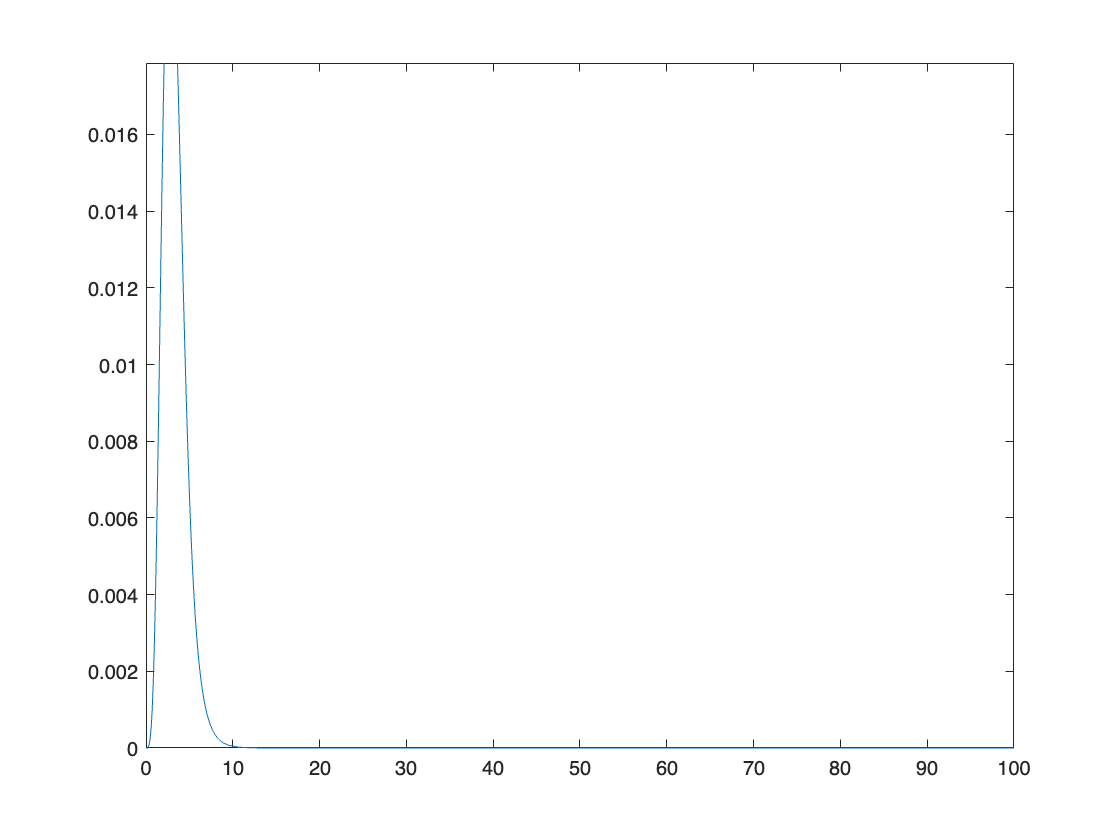

fplot(K,[0,100])

Se observa din grafic ca functia nu isi schimba semnul, deci putem aplica corolarul lui Peano:

Rf = 1 / factorial(gr_maxim+1) * simplify(RR(@(x) x^(gr_maxim+1), rA1, rA2, rA3, rA4, rt3, rt4)) * subs(diff(f(x), x, gr_maxim+1), x, xi)

$$Rf = \frac{\frac{\partial^{6}}{\partial \xi^{6}}f\left(\xi \right)}{15}$$

Deci, am obtinut urmatoarele:


$$\begin{array}{l}
\int_0^{\infty } e^{-t} f\left(t\right)\mathrm{dt}=\;Q\left(f\right)+R\left(f\right)\\
Q\left(f\right)=\frac{11f\left(0\right)}{18}+\frac{f^{\prime } \left(0\right)}{6}+\frac{3f\left(2\right)}{8}+\frac{f\left(6\right)}{72}\\
R\left(f\right)=\frac{f^{\left(6\right)} \left(\xi \right)}{15}
\end{array}$$


### Alternativa

Fie $\pi_2$ polinomul ortogonal pe intervalul $\left\lbrack 0,\infty \right\rbrack$ in raport cu ponderea $w_2 \left(t\right)=w\left(t\right)\dot{{\;\cdot \;t}^2 }$

% syms t;
% w=exp(-t);
% w2=t^2*w;
% pi2=orto_poly_sym(w2,t,sym(0),sym(inf),2)
% roots=solve(pi2==0)'
% nodes=[0 0 roots]

In mod similar ca anterior, gasim $A_1 ,A_2 ,A_3 ,\;A_4$ din momentele ponderii si gradul maxim de exactitate al cuadraturii (5).